# Trabajo 3 - Teoría de las telecomunicaciones 1

**Universidad del Cauca - 2021-1**

**Grupo A12 - Nicolás Chicaiza y Nicolás Zambrano**

clear; %Limpio Espacio de trabajo
clc;

## 1. GRAFICA DE SEÑAL ASIGNADA

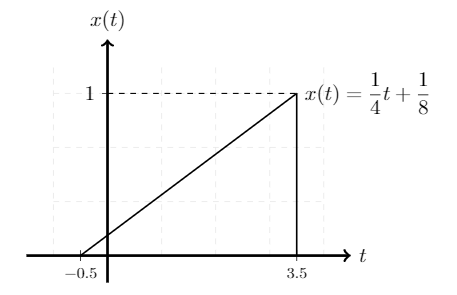

## 2. SEÑAL ORIGINAL Y PARAMETROS

A=1; %Amplitud rampa (Multiplicacion por un escalar)
sh=0.5; %Desplazamiento en el tiempo (Normalizado solo para valores positivos)
T=4; %Periodo rampa (Igual al taller 1)
esc=1; %Cambio de Escala
shf=0; %Desplazamiento en frecuencia
np=0.001; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
fs=1/(T*np); %Frecuencia de muestreo
t=-(T+sh):np*T:(T+sh); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)
ramp=(A/T)*((t*esc)+sh); %Defino la pendiente de las rampas y creo el vector rampa con respecto al tiempo
ps=ramp.*rectpuls(((t*esc)+sh)-(T/2),(T)); %Acoto el vector rampa con un pulso rectangular de origen en 0 y ancho Tr
ps=ps.*exp(i*2*pi*shf*t);

## 3. CONVERSION DE LA SEÑAL AL DOMINIO DE LA FRECUENCIA

### 3.1 Cálculo FFT

Pt=100 ;%Coeficiente multiplicador de cantidad de puntos en la transformada rapida de Fourier
N=Pt*(2^(nextpow2(length(ps))));%Calculo de la potencia de 2 mas cercana a la longitud de la señal de entrada (Para eficiencia computacional)
Tf=fft(ps,N);
Xf=abs(fftshift(Tf))/fs; % Transformada FFT Normalizada
%Af=angle(fftshift(Tf))/fs;
f=linspace(-fs/2,fs/2,length(Xf));
%f=f./T;%Normalizacion en frecuencia
%-----------------------------------------------------------------------------
%wt = conv(ht,ps);% Filtro aplicado en el dominio del tiempo
%f=linspace(-fs/2,fs/2,length(w));
%plot(fsimb,w,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;%xlim([-3 3]); %Graficacion de Resultados
%title('\bf Espectro de magnitud de la señal filtrada');


### 3.2 Cálculo FFT Inversa

ratioabs=N/length(t); %razon entre el tamaño del vector tiempo y el tamaño del vector de la transformada de Fourier
Xt=abs(fftshift(fft(Tf))/N); % Transformada FFT Normalizada
ti=linspace(-ratioabs*(T+sh),ratioabs*(T+sh),length(Xt)); %Espacio vectorial del tiempo normalizado
ti=ti+(T+sh); %corrimiento del vector tiempo para ajuste de desfase
%-----------------------------------------------------------------------------

## 4. CONSTRUCCIÓN DE FILTROS

### 4.1 Construcción Filtro Ideal Pasabajas

sym f;
K = 1; % Amplitud del espectro (pulso rectangular)
B =2; % Ancho de Banda pasante del Filtro
hf = K*rectpuls(f,2*B); % Función del filtro ideal en el dominio de la frecuencia

### 4.2 Construcción Filtro Trapezoidal

anc=4;%Ancho de la region constante del trapezoide
anr=1;%Ancho de la rampa del trapezoide
b=anc+anr;
a=anr;%Caracteristica variable del primer sinc
SincA=sinc(a.*t);%funcion sinc A en el dominio temporal
SincB=sinc(b.*t);%funcion sinc B en el dominio temporal
rft=(b).*(SincA.*SincB);%Multiplicacion de sinc en el dominio temporal
hft=fft(rft,N);%Paso 1: Transformada de fourier de la funcion de transferencia del filtro temporal (hacia dominio de la frecuencia)
Htr=abs(fftshift(hft))/fs; %Paso 2: Transformada de fourier de la funcion de transferencia del filtro temporal (hacia dominio de la frecuencia)
% plot(t,SincA,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-2*B 2*B]); %Graficacion de Resultados
% title('\bf Filtro Trapezoidal');
% plot(t,SincB,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-2*B 2*B]); %Graficacion de Resultados
% title('\bf Filtro Trapezoidal');

## 5. FILTRADO Y RETORNO AL DOMINIO TEMPORAL

### 5.1 Filtro Ideal

w = fftshift(Tf).*hf;% Filtro ideal aplicado en el dominio de la frecuencia
wf=abs(w)/fs; % Transformada FFT Normalizada
wt=abs(fftshift(fft(w))/N); % Transformada IFFT Normalizada

### 5.2 Filtro Trapezoidal

wtr= fftshift(Tf).*Htr;% Filtro trapezoidal aplicado en el dominio de la frecuencia
wtrf=abs(wtr)/fs; % Transformada FFT Normalizada
wtrt=abs(fftshift(fft(wtr))/N); % Transformada IFFT Normalizada

## 6. TEOREMA DE RAILEIGH

rayoriginalt=trapz(ti,(abs(Xt)).^2)%Integral del teorema de rayleigh sobre la señal original en el Tiempo

rayoriginalt = 1.3307

rayoriginalf=trapz(f,(abs(Xf)).^2)%Integral del teorema de rayleigh sobre la señal original en Frecuencia

rayoriginalf = 1.3313

### 6.1 Filtro Ideal

rayidealt=trapz(ti,(abs(wt)).^2,2)%Integral del teorema de rayleigh sobre la señal filtrada con el filtro ideal en el Tiempo

rayidealt = 1.3055

rayidealf=trapz(f,(abs(wf)).^2,2)%Integral del teorema de rayleigh sobre la señal filtrada con el filtro ideal en Frecuencia

rayidealf = 1.3061

### 6.2 Filtro Trapezoidal

raytrapezoidalt=trapz(ti,(abs(wtrt)).^2)%Integral del teorema de rayleigh sobre la señal filtrada con el filtro trapezoidal en el Tiempo

raytrapezoidalt = 1.3089

raytrapezoidalf=trapz(f,(abs(wtrf)).^2)%Integral del teorema de rayleigh sobre la señal filtrada con el filtro trapezoidal en Frecuencia

raytrapezoidalf = 1.3094

## 7. GRAFICAS DE RESULTADOS

### 7.1 Resultados Filtro Ideal

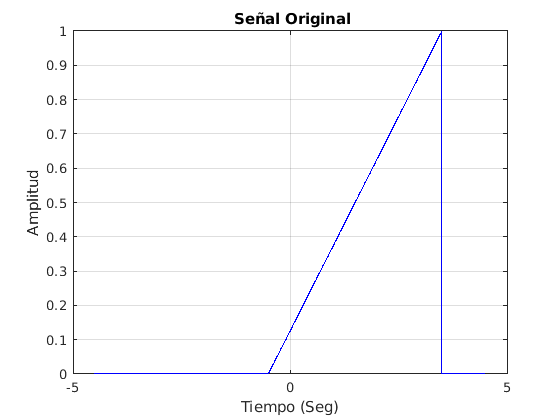

plot(t,abs(ps),'b'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf Señal Original');

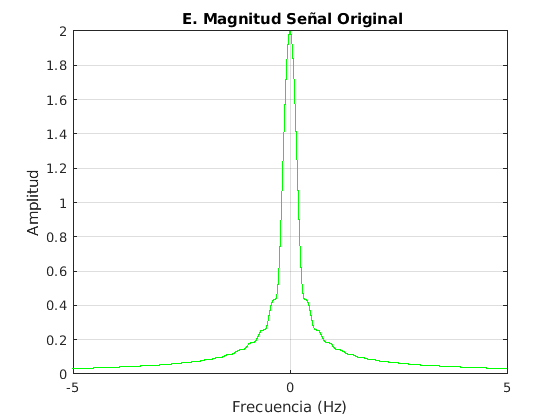

plot(f,Xf,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf E. Magnitud Señal Original');

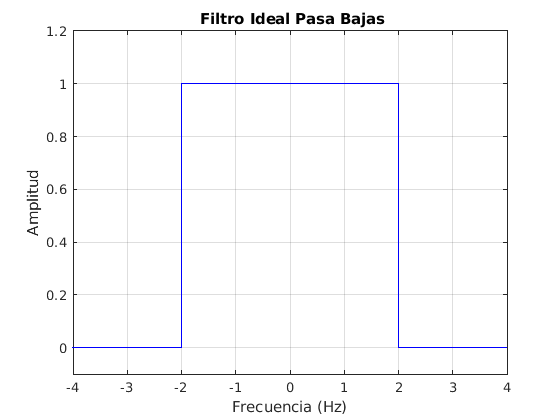

plot(f,hf,'b'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-2*B 2*B]);ylim([-0.1 1.2]) %Graficacion de Resultados
title('\bf Filtro Ideal Pasa Bajas');

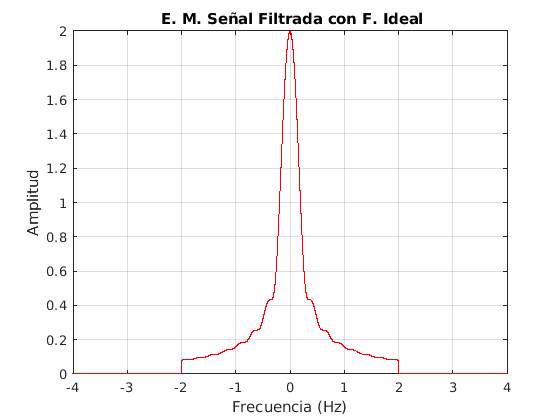

plot(f,wf,'r'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-2*B 2*B]); %Graficacion de Resultados
title('\bf E. M. Señal Filtrada con F. Ideal');

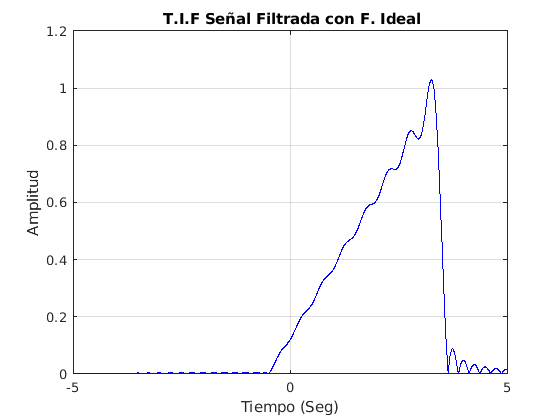

plot(-ti,wt,'b'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf T.I.F Señal Filtrada con F. Ideal');

### 7.2 Resultados Filtro Trapezoidal

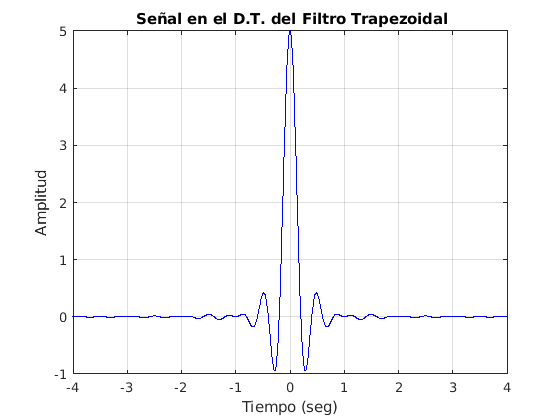

plot(t,rft,'b'),grid on,xlabel 'Tiempo (seg)', ylabel Amplitud;xlim([-2*B 2*B]); %Graficacion de Resultados
title('\bf Señal en el D.T. del Filtro Trapezoidal');

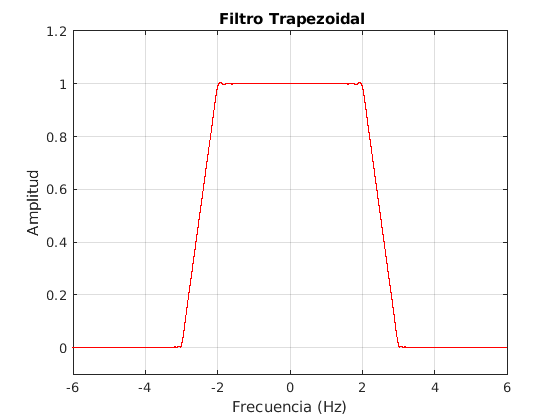

plot(f,Htr,'r'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-(anr+anc+1) (anr+anc+1)]);ylim([-0.1 1.2]) %Graficacion de Resultados
title('\bf Filtro Trapezoidal');

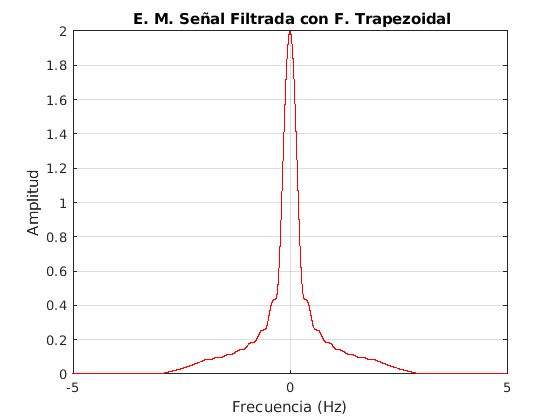

plot(f,wtrf,'r'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf E. M. Señal Filtrada con F. Trapezoidal');

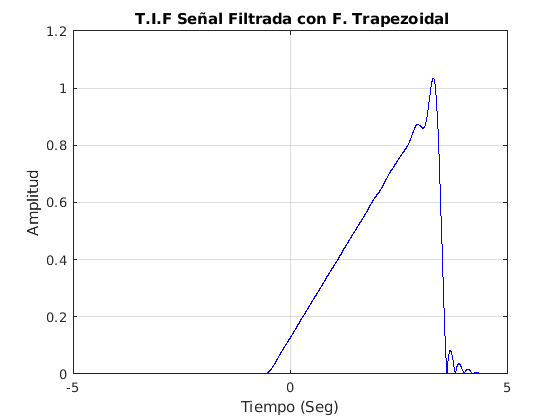


%plot(-ti,Xt,'black'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
%title('\bf Transformada Inversa de Fourier Señal Original');



plot(-ti,wtrt,'b'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf T.I.F Señal Filtrada con F. Trapezoidal');